tic;

img_rgb = imread('input.tif');
img_rgb = im2double(img_rgb);

img_hsv = rgb2hsv(img_rgb);

H = img_hsv(:,:,1);  % Hue: 0–1
S = img_hsv(:,:,2);  % Saturation: 0–1

%Skalowanie Hue do 0–179 i Saturation do 0–255
H = floor(H * 179); 
S = floor(S * 255);

hist2d = zeros(180, 256);

[rows, cols] = size(H);
for i = 1:rows
    for j = 1:cols
        hue = H(i,j) + 1;
        sat = S(i,j) + 1;
        hist2d(hue, sat) = hist2d(hue, sat) + 1;
    end
end

elapsedTime = toc;
disp(['Czas wykonania: ', num2str(elapsedTime), ' sekund']);
hist2d = hist2d / max(max(hist2d));
parula_map = parula(64);
idx_map = round(hist2d * 63) + 1;

[h, w] = size(hist2d);
hist_matlab = zeros(h, w, 3);

for ch = 1:3
    channel = reshape(parula_map(idx_map(:), ch), h, w);
    hist_matlab(:,:,ch) = channel;
end

imshow(hist_matlab);
title('2D HSV Histogram with Parula Colormap');

hist2d_openCL = imread("outputHist2D_openCL.bmp");
imshow(hist2d_openCL)

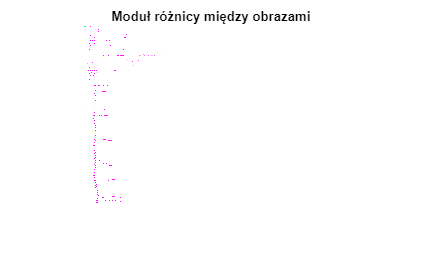

img1 = hist2d_openCL;
img2 = hist_matlab;

img1 = im2double(img1);
img2 = im2double(img2);

% Obliczenie modułu różnicy
diff_abs = abs(img1 - img2) * 255;

% Wyświetlenie różnicy
imshow(diff_abs);
title('Moduł różnicy między obrazami');

imwrite(diff_abs, 'roznica_modul.png');